# DMRG: Single-site update for ground state search

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we will obtain the ground state of one-dimensional systems by using the **density-matrix renormalization group (DMRG)**. 

## XY spin chain: ground state search

The first example to solve is the XY spin chain, where spin-1/2's lie along a one-dimensional lattice of length $L$ and the spins have nearest-neighbor interaction. The name "XY" comes from that only the $x$ and $y$ components of the neighboring spins are coupled:


$$\hat{H}_{\mathrm{XY}}
= -\sum_{\ell=1}^{L-1} (\hat{S}_{\ell,x} \hat{S}_{\ell+1,x} + \hat{S}_{\ell,y} \hat{S}_{\ell+1,y})
= -\frac{1}{2} \sum_{\ell=1}^{L-1} (\hat{S}_{\ell,+} \hat{S}_{\ell+1,-} + \hat{S}_{\ell,-} \hat{S}_{\ell+1,+}) .$$


By using the [Jordan-Wigner transformation](https://en.wikipedia.org/wiki/Jordan%E2%80%93Wigner_transformation), the XY model is mapped onto a non-interacting tight-binding chain of spinless fermions. So the model is exactly solvable, though we numerically diagonalized the single-particle Hamiltonians in the previous exercises. As shown in those exercises, the tight-binding chain show different behaviors (e.g., ground-state degeneracy) depending on the parity of $L$. Here we focus on even $L$, where the ground-state energy is


$$E_{0} = \frac12 - \frac{1}{2\sin \frac{\pi}{2(N+1)}} ,$$


and the correlation function of nearest-neighbor spins with respect to the ground state is


$$\langle \Psi_0 |\hat{S}^+_\ell \hat{S}^-_{\ell+1} | \Psi_0 \rangle = \langle \Psi_0 | \hat{S}^-_\ell \hat{S}^+_{\ell+1} | \Psi_0 \rangle = -\frac{1}{2(N+1)} \left[  \frac{(-1)^\ell}{\sin\frac{(2\ell+1)\pi}{2(N+1)}} - \frac{1}{\sin\frac{\pi}{2(N +1)}} \right] ,$$


where $| \Psi_0 \rangle$ means the ground state of the XY model. 

We will implement the single-site DMRG method and compare the DMRG result with the exact one. Let's first set the parameters for the Hamiltonian and the DMRG routine.

clear

% system parameter
J = -1; % coupling strength
L = 40; % number of sites in a chain

% DMRG parameter
Nkeep = 30; % bond dimension
Nsweep = 4; % number of pairs of left+right sweeps

% Local operators
[S,I] = getLocalSpace('Spin',1/2);

Now we construct the bulk tensor for the MPO representation of the XY spin chain Hamiltonian. The tensor comprises the $L-2$ tensors of the MPO, except for the first and last tensors on the boundaries; hence bulk.

% % MPO formulation of Hamiltonian
% Hamiltonian tensor for each chain site
Hloc = cell(4,4);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
Hloc{2,1} = S(:,:,1);
Hloc{3,1} = S(:,:,3);
Hloc{4,2} = J*S(:,:,1)';
Hloc{4,3} = J*S(:,:,3)';
Hloc{end,end} = I;
Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));

% full chain
Hs = cell(1,L);
Hs(:) = {Hloc};
Hs{1} = Hs{1}(:,:,end,:); % choose the last components of the left leg
Hs{end} = Hs{end}(:,:,:,1); % choose the first components of the right leg

## Exercise (a): Initialize MPS with the iterative diagonalization result

Before starting the iterative ground state search, we need to specify an MPS as the starting point. For this, one can use either the iterative diagonalization result or random tensors. Write the code that performs **iterative diagonalization with the MPO Hamiltonian.** At each iteration, keep at most `Nkeep` states, **without** keeping degenerate states near truncation thresholds altogether (or discard them altogether). Obtain an MPS represented by a cell array `Minit`, where `Minit{n}` is a rank-3 tensor for site n.

## Exercise (b): Complete the single-site DMRG function

There is a function `DMRG_GS_1site_Ex.m`, which is in the same sub-directory with this script. It is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`. Don't forget to also complete its sub-function `eigs_1site_GS`!

You can verify your solutions to Exercises (a) and (b) by comparing them with the exact results. Upon successful implementation, the `DMRG_GS_1site_Ex` function will run like:

[M0,E0,Eiter] = DMRG_GS_1site_Ex(Minit,Hs,Nkeep,Nsweep);

22-09-23 20:58:42 | Single-site DMRG: ground state search
22-09-23 20:58:42 | # of sites = 40, Nkeep = 30, # of sweeps = 4 x 2
22-09-23 20:58:42 | Sweep #1/8 (right -> left) : Energy = -12.55385
22-09-23 20:58:42 | Sweep #2/8 (left -> right) : Energy = -12.5539
22-09-23 20:58:42 | Sweep #3/8 (right -> left) : Energy = -12.5539
22-09-23 20:58:43 | Sweep #4/8 (left -> right) : Energy = -12.5539
22-09-23 20:58:43 | Sweep #5/8 (right -> left) : Energy = -12.5539
22-09-23 20:58:43 | Sweep #6/8 (left -> right) : Energy = -12.5539
22-09-23 20:58:43 | Sweep #7/8 (right -> left) : Energy = -12.5539
22-09-23 20:58:43 | Sweep #8/8 (left -> right) : Energy = -12.5539
Elapsed time: 1.416s, CPU time: 15.79s, Avg # of cores: 11.15


Compare the DMRG result of the ground-state energy, `E0`, with the exact value.

E0_exact = 0.5 - (1/2/sin(pi/2/(L+1))); % exact value
disptime(['Exact GS energy = ',sprintf('%.5g',E0_exact),', DMRG = ', ...
    sprintf('%.5g',E0),', error = ',sprintf('%.5g',E0-E0_exact)]);

22-09-23 20:58:43 | Exact GS energy = -12.554, DMRG = -12.554, error = 9.6503e-07


Plot how the expectation value of the Hamiltonian converges to the exact value as iteration proceeds.

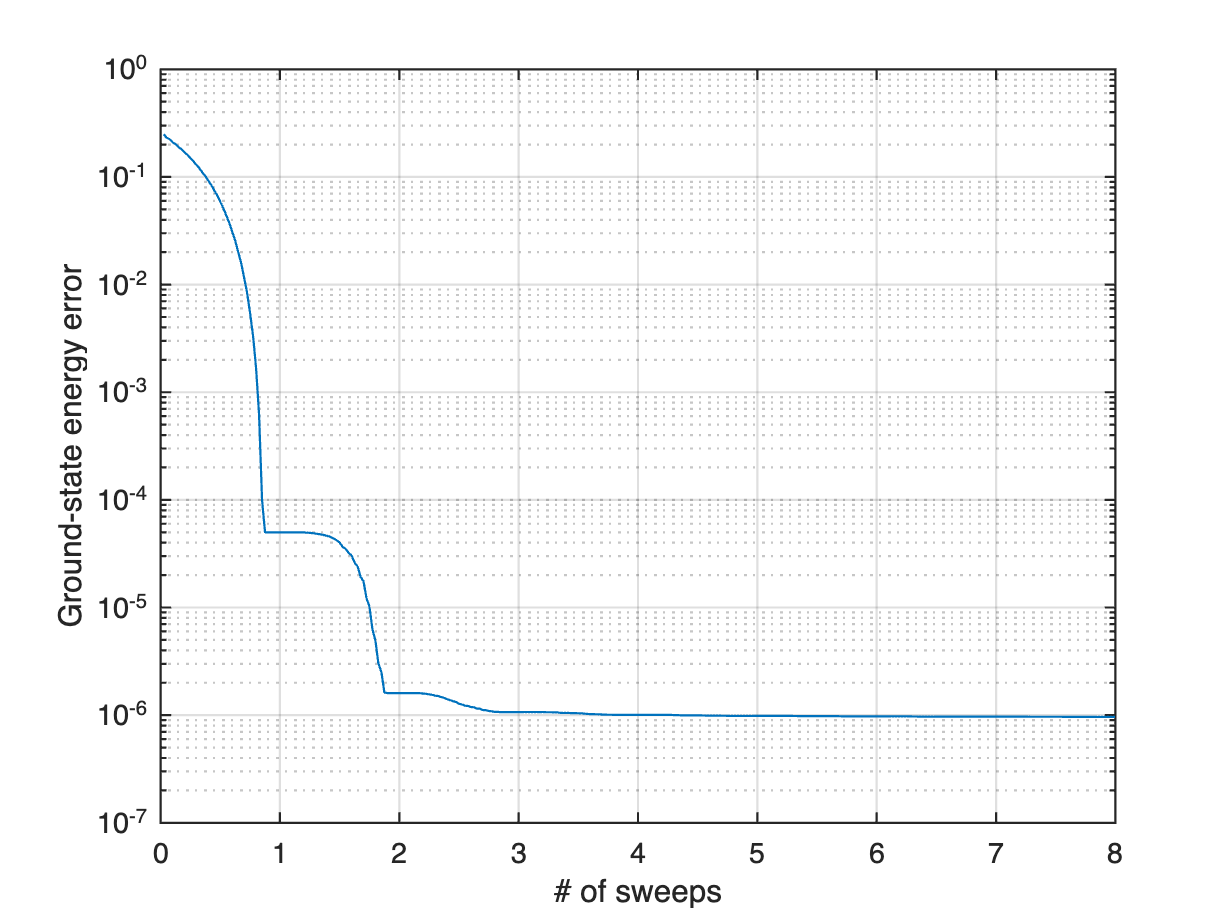

figure;
semilogy((1:numel(Eiter))/L,Eiter(:)-E0_exact,'LineWidth',1);
set(gca,'FontSize',13,'LineWidth',1);
xlim([0 2*Nsweep]);
grid on;
xlabel('# of sweeps');
ylabel('Ground-state energy error');

The error is $O(10^{-6})$. The error can be further decreased by increasing bond dimension `Nkeep`. Indeed, the accuracy is bound by finite bond dimension, since the system is gapless. Consider a bipartition of the chain, into left and right halves. The entanglement between two parts in the ground state increases with the system size $L$ logarithmically, for the gapless systems. Thus, to achieve the same accuracy, we should use larger bond dimension that increases as the power law of $L$.

On the other hand, for the gapped systems, high accuracy can be achieved with small bond dimensions. For example, the AKLT model needs only the bond dimension 2.

## Spin-spin correlation function

Compute the spin-spin correlation function $\langle \Psi_0 | \hat{S}_{\ell,+} \hat{S}_{\ell+1,-} | \Psi_0 \rangle$, i.e., the expectation value of the product of spin-raising and -lowering operators at nearest-neighbor sites with respect to the ground state $|\Psi_0\rangle$. Be aware of that the result MPS `M` is in a left-canonical form, as mentioned in the documentation of `DMRG_GS_1site_Ex.m`.

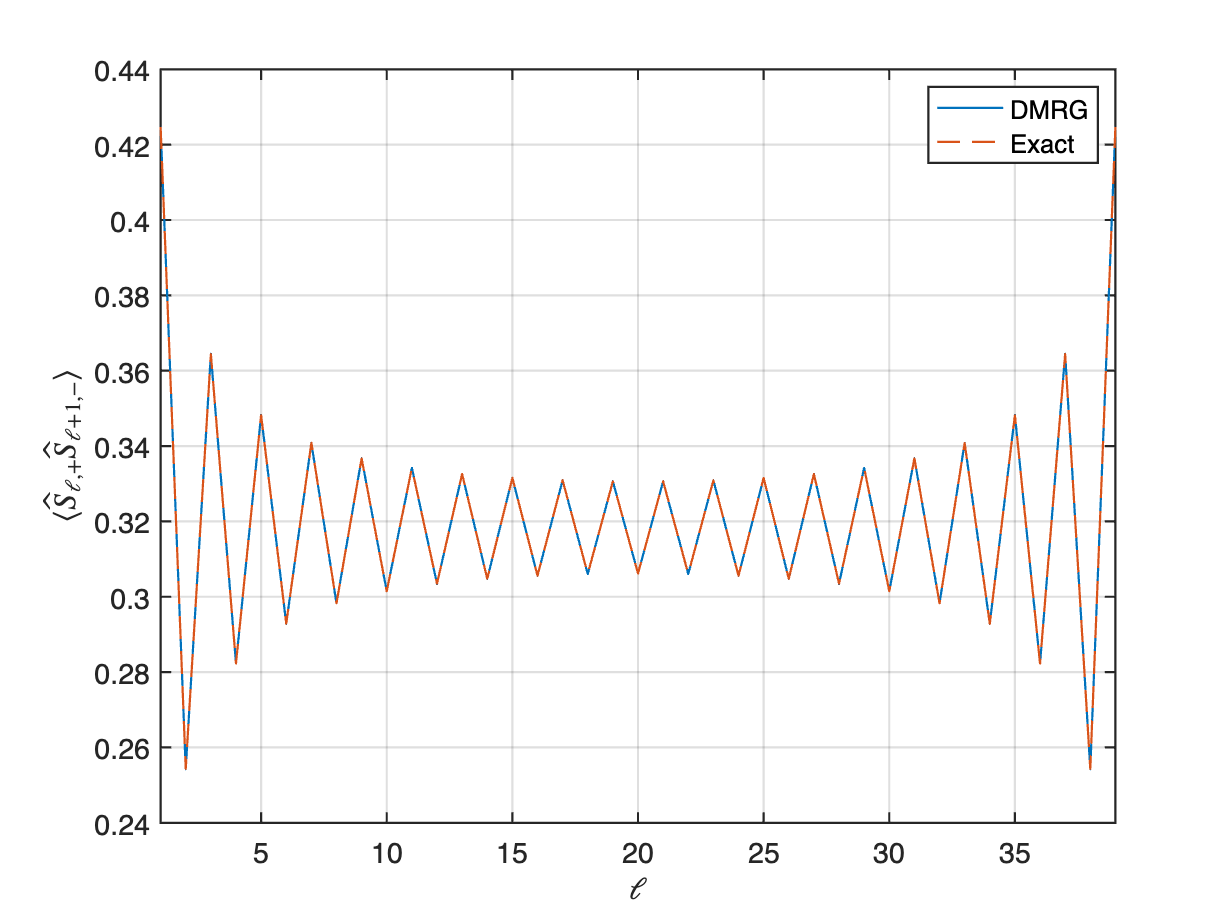

% compute correlation function for the nearest-neighbour spins
SS = zeros(1,L-1);
for itN = (2:L)
    T = updateLeft([],[],M0{itN-1},S(:,:,1)*sqrt(2),3,M0{itN-1});
    T = updateLeft(T,3,M0{itN},S(:,:,3)*sqrt(2),3,M0{itN});
    
    for itN2 = ((itN+1):L)
        T = updateLeft(T,2,M0{itN2},[],[],M0{itN2});
    end
    
    SS(itN-1) = T;
end

% exact relation
SS_exact = (((-1).^(1:L-1))./sin((2*(1:L-1)+1)*pi/2/(L+1)) - ...
    1./sin(pi/2/(L+1)))/(-2*(L+1));

figure;
plot((1:L-1),SS,'-',(1:L-1),SS_exact,'--','LineWidth',1);
legend({'DMRG','Exact'});
set(gca,'FontSize',13,'LineWidth',1);
xlabel('$\ell$','Interpreter','latex');
ylabel('$\langle \hat{S}_{\ell,+} \hat{S}_{\ell+1,-} \rangle$', ...
    'Interpreter','latex');
xlim([1 L-1]);
grid on;

The numerical result and the exact result coincide nicely!